# WInner-take-all theory: 1L5E as receiver 

# investigate the layer-dependent activities and interation among populations

clear;
close all;
clc;
initime = clock;
addpath('../funcs');
figpath = '../../report/figures/';

condition = {'Original', 'Condition: S1', 'Condition: S2','Condition: S1S2','Condition: S1S2+A1','Condition: S1S2+A2'};
titleFont = 20;
layers = {'L2/3', 'L4', 'L5', 'L6'};
colors = ["#EA4335", "#FBBC05", "#4285F4", "#34A853"];

Delta_e = 0.3;
Delta_i = 0.032;
Iattn = 0.02;
allTime = 4000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, allTime);
r = r*1000;
PETC = getPET(v(:,350000:400000,:),g(:,:,350000:400000,:));
PET0 = getPET(v(:,50000:100000,:),g(:,:,50000:100000,:));
PET(:,:,1) = PET0(:,:,1);
PET(:,:,2:6) = PETC;
env = getEnvelope(r);

     1

     1

     1

     1

     1

     2

     2

     2

     2

     2

     3

     3

     3

     3

     3

     4

     4

     4

     4

     4

     5

     5

     5

     5

     5

     6

     6

     6

     6

     6

     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     8

     8

     8

     8

     8

     9

     9

     9

     9

     9

    10

    10

    10

    10

    10

    11

    11

    11

    11

    11

    12

    12

    12

    12

    12

    13

    13

    13

    13

    13

    14

    14

    14

    14

    14

    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    16

    16

    16

    16

    16



% scatter(0.3, 0.027,30, "x","MarkerEdgeColor","k","LineWidth",1);
% scatter(0.3, 0.032,30, "+","MarkerEdgeColor","k","LineWidth",1);


## Firing rate by layers

level = getLevel(r, 350000, 400000);

Pop number: 7, Condition number:0, ENTERED second round findpeaks.
Pop number: 7, Condition number:1, ENTERED second round findpeaks.
Pop number: 7, Condition number:2, ENTERED second round findpeaks.
Pop number: 7, Condition number:3, ENTERED second round findpeaks.
Pop number: 7, Condition number:4, ENTERED second round findpeaks.
Pop number: 15, Condition number:0, ENTERED second round findpeaks.
Pop number: 15, Condition number:1, ENTERED second round findpeaks.
Pop number: 15, Condition number:2, ENTERED second round findpeaks.
Pop number: 15, Condition number:3, ENTERED second round findpeaks.
Pop number: 15, Condition number:4, ENTERED second round findpeaks.


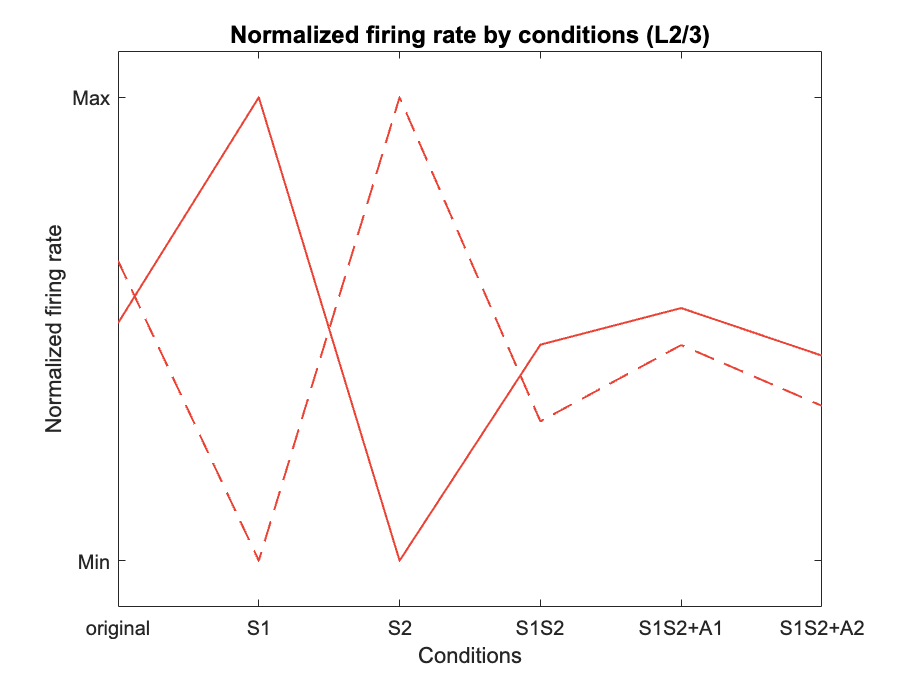

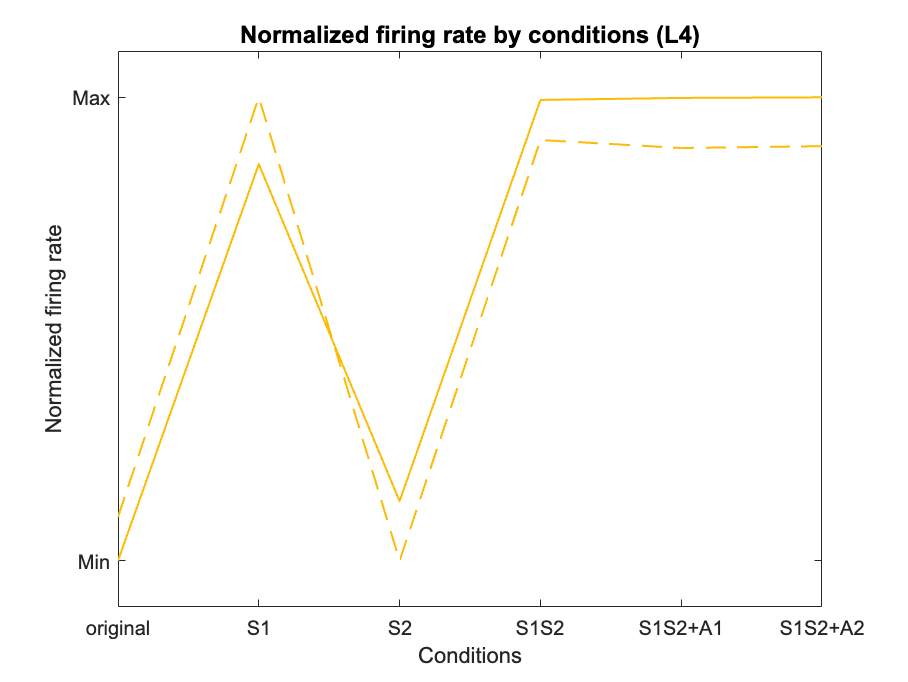

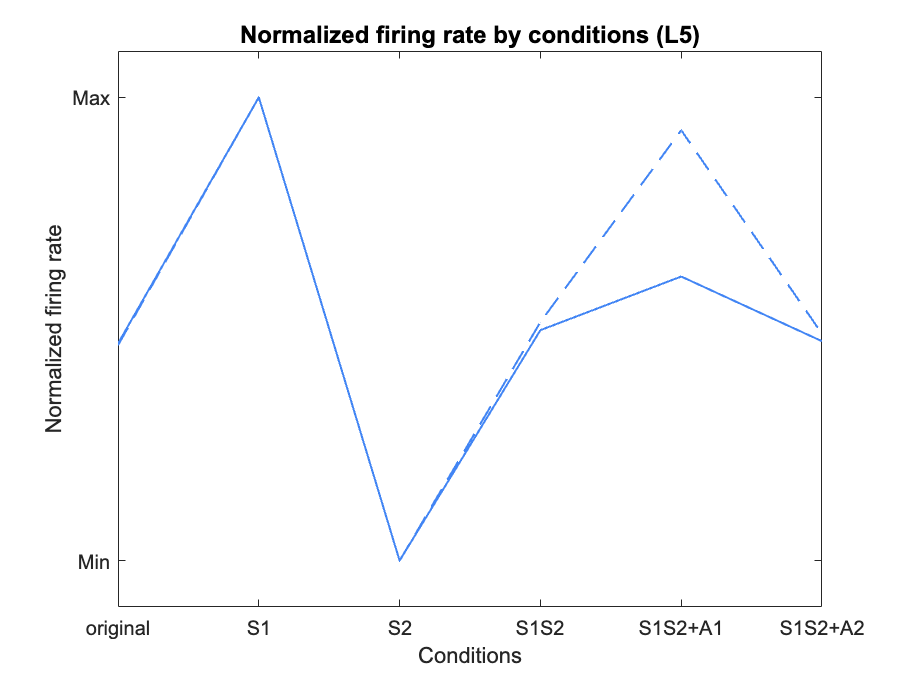

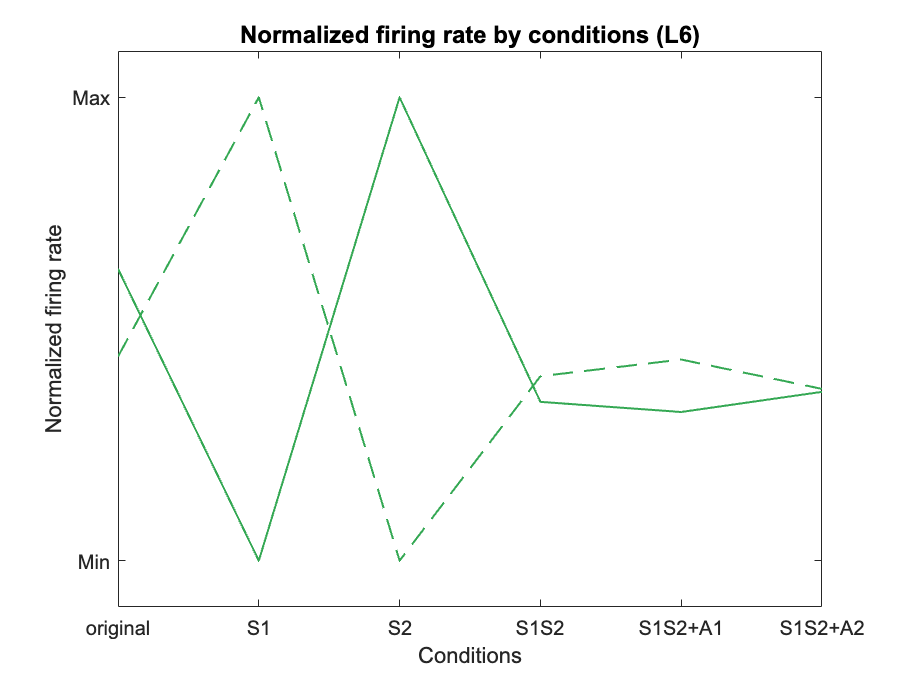

level_norm = normBetween01(level,2);
condax = [1 2 3 4 5 6];
for layer = 1:4
    figure();
    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(condax, level_norm(pop_E,:),'Color',colors(layer), 'LineWidth',1);
    hold on;
    plot(condax, level_norm(pop_I,:),"--",'Color',colors(layer), 'LineWidth',1);

    ylabel("Normalized firing rate");
    xlabel("Conditions");
    xticks([1 2 3 4 5 6]);
    xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    
    title(append("Normalized firing rate by conditions (", layers(layer),")"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'fr_','L',num2str(layer));
    print(filename, '-dpng', '-r600');

end

## percentage line chart filled with color by condition

## percentage line chart filled with color by Delta_E/I